## Example

### Unit ball sampling

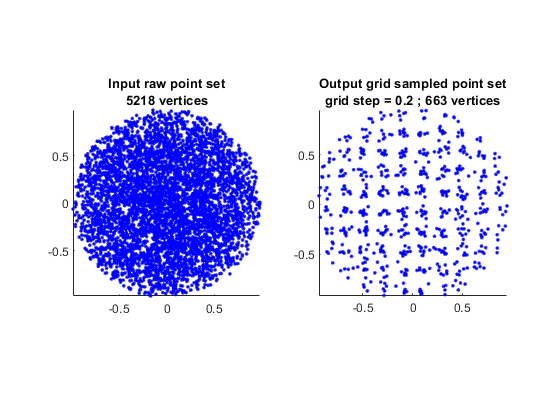

N = 1e4;
X = 2*(rand(N,1)-0.5);
Y = 2*(rand(N,1)-0.5);
Z = 2*(rand(N,1)-0.5);

Rho = X.^2 + Y.^2 + Z.^2;
i = Rho <= 1;
X = X(i);
Y = Y(i);
Z = Z(i);

M = [X, Y, Z];
grid_step = 0.2;
N = point_set_grid_simplify(M, grid_step);

figure;
subplot(121);
plot3(X,Y,Z,'.','Color',[0 0 1],'Linewidth',2), hold on;
axis equal, view(2);
title({'Input raw point set',cat(2,num2str(size(M,1)),' vertices')});

subplot(122);
plot3(N(:,1), N(:,2), N(:,3),'.','Color',[0 0 1],'Linewidth',2), hold on;
axis equal, view(2);
title({'Output grid sampled point set',cat(2,'grid step = ', num2str(grid_step),' ; ',num2str(size(N,1)),' vertices')});